# 3D Printer Data Exploration

## Load Data

clear;
load 'houseprint';

## Test Log Data

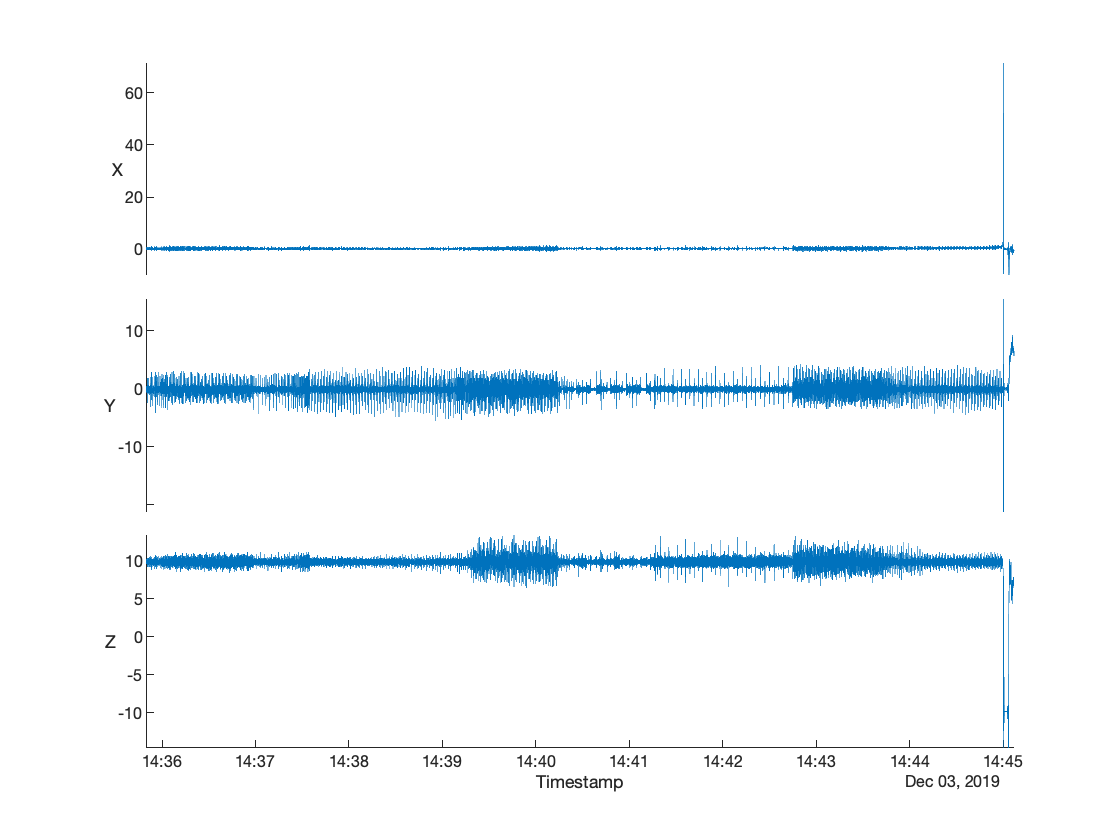

ans =   StackedLineChart with properties:

         SourceTable: [56007×3 timetable]
    DisplayVariables: {'X'  'Y'  'Z'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


stackedplot(Acceleration)

a = timetable2table(Acceleration)

a = 56007×4 table
           Timestamp               X            Y          Z   
    ________________________    ________    _________    ______

    03-Dec-2019 14:35:49.718      0.0964      -0.2157    10.037
    03-Dec-2019 14:35:49.727     0.61417     0.061522    9.5879
    03-Dec-2019 14:35:49.737     0.16136     -0.34548    10.027
    03-Dec-2019 14:35:49.747     0.22348    -0.071701    9.7377
    03-Dec-2019 14:35:49.757     0.63648      0.31465    9.6965
    03-Dec-2019 14:35:49.767    0.023052     -0.33306    10.139
    03-Dec-2019 14:35:49.777     0.15163     -0.48215    9.5775
    03-Dec-2019 14:35:49.787     0.49966    -0.067061    9.7045
    03-Dec-2019 14:35:49.797     0.18427      0.25806    10.119
    03-Dec-2019 14:35:49.807     0.20911     -0.17603    9.6221
    03-Dec-2019 14:35:49.817     0.36898     -0.32632    9.7307
    03-Dec-20

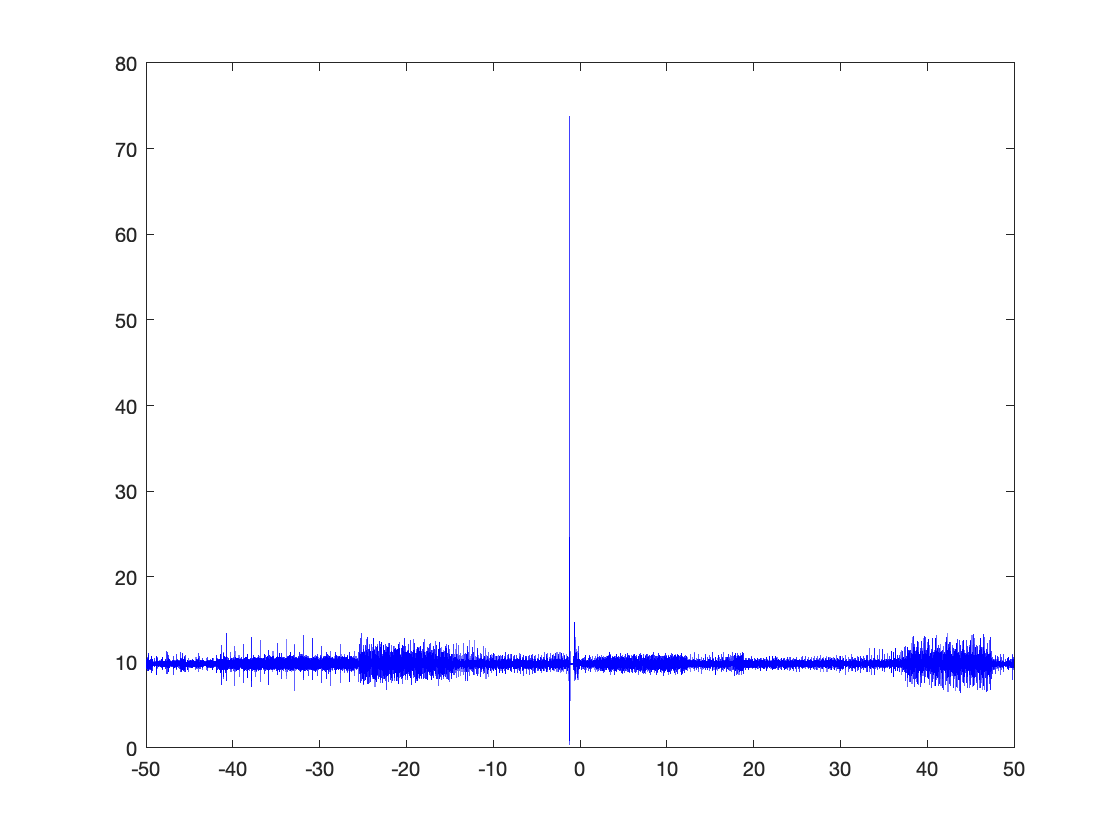

accelData = [a.X a.Y a.Z]';
x = vecnorm(accelData);
% x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
plot(f,fftshift(abs(x)),'b');